# Irminger 5 CTD Casts

First produces a rough map of the CTD casts from Irminger 5 in the vicinity of OOI assets. Each CTD cast is then plotted for temperature, salinity, and dissolved oxygen. 

Kristen Fogaren 12/3/2020

- Data was downloaded from Alfresco

- Data conversion with Seabird Software

- Processed casts in Python and output to CSV

- Read into Matab as tables

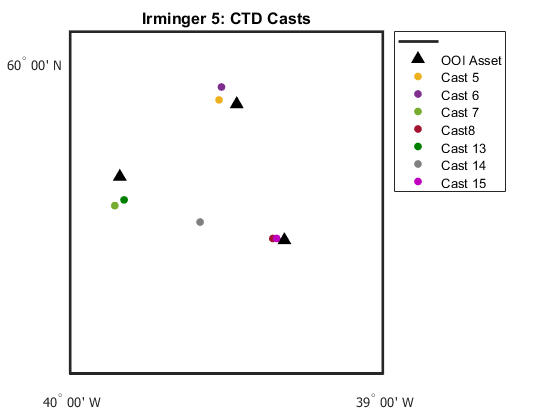

% Set up workspace 
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\My Drive\Matlab_work\BC\IrmingerData\Year5')
load Irm5_CTD_Casts.mat

% OOI asset locations 
ooi_latlon = [59.9341, -39.4673
    59.8177, -39.8412
    59.7155, -39.3148];
    
% Setup the Map Axes
figure
axesm('MapProjection','mercator'); 
minlat=min(ooi_latlon(:,1)); maxlat=max(ooi_latlon(:,1)); 
minlon=min(ooi_latlon(:,2)); maxlon=max(ooi_latlon(:,1)); 

% New Lat/Lon Limits
ll = [-40 59.5; -39 60.05];

setm(gca, 'MapLatLimit',[ll(1,2) ll(2,2)],...
          'MapLonLimit',[ll(1,1) ll(2,1)]);
setm(gca,'MLineLocation',1,'MLabelLocation',1,...
    'MeridianLabel','on','MLabelParallel','south'); 
setm(gca,'PLineLocation',1,'PLabelLocation',1,...
    'ParallelLabel','on','PLabelMeridian','west');
tightmap;
setm(gca,'FontWeight','normal','FontSize',10,'FontName','Tahoma','LabelUnits','dm'); 

% Add lat/lon tickmarks for every degree if the map spans 
% greater than 1.5 degrees longitude, or every quarter degree if less.
if abs(maxlon-minlon)>1.5
  setm(gca,'MLineLocation',1,'MLabelLocation',1,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',1,'PLabelLocation',1,'ParallelLabel','on','PLabelMeridian','west');
else
  setm(gca,'MLineLocation',0.25,'MLabelLocation',0.25,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',0.25,'PLabelLocation',0.25,'ParallelLabel','on','PLabelMeridian','west');
end

% Plot Casts/OOI Assets
plotm(ooi_latlon(:,1),ooi_latlon(:,2),'^','markersize',8,'MarkerFaceColor','k',...
    'MarkerEdgeColor','k')
hold on
plotm(nanmean(ar3003005down.latitude),nanmean(ar3003005down.longitude),'.','markersize',20,'Color',yellow)
plotm(nanmean(ar3003006down.latitude),nanmean(ar3003006down.longitude),'.','markersize',20,'Color',purple)
plotm(nanmean(ar3003007down.latitude),nanmean(ar3003007down.longitude),'.','markersize',20,'Color',green)
plotm(nanmean(ar3003008down.latitude),nanmean(ar3003008down.longitude),'.','markersize',20,'Color',maroon)
plotm(nanmean(ar3003013down.latitude),nanmean(ar3003013down.longitude),'.','markersize',20,'Color',forestgreen)
plotm(nanmean(ar3003014down.latitude),nanmean(ar3003014down.longitude),'.','markersize',20,'Color',grey)
plotm(nanmean(ar3003015down.latitude),nanmean(ar3003015down.longitude),'.','markersize',20,'Color',brightpurple)

title('Irminger 5: CTD Casts')
legend('','OOI Asset','Cast 5','Cast 6','Cast 7','Cast8',...
    'Cast 13','Cast 14','Cast 15','Location','bestoutside')

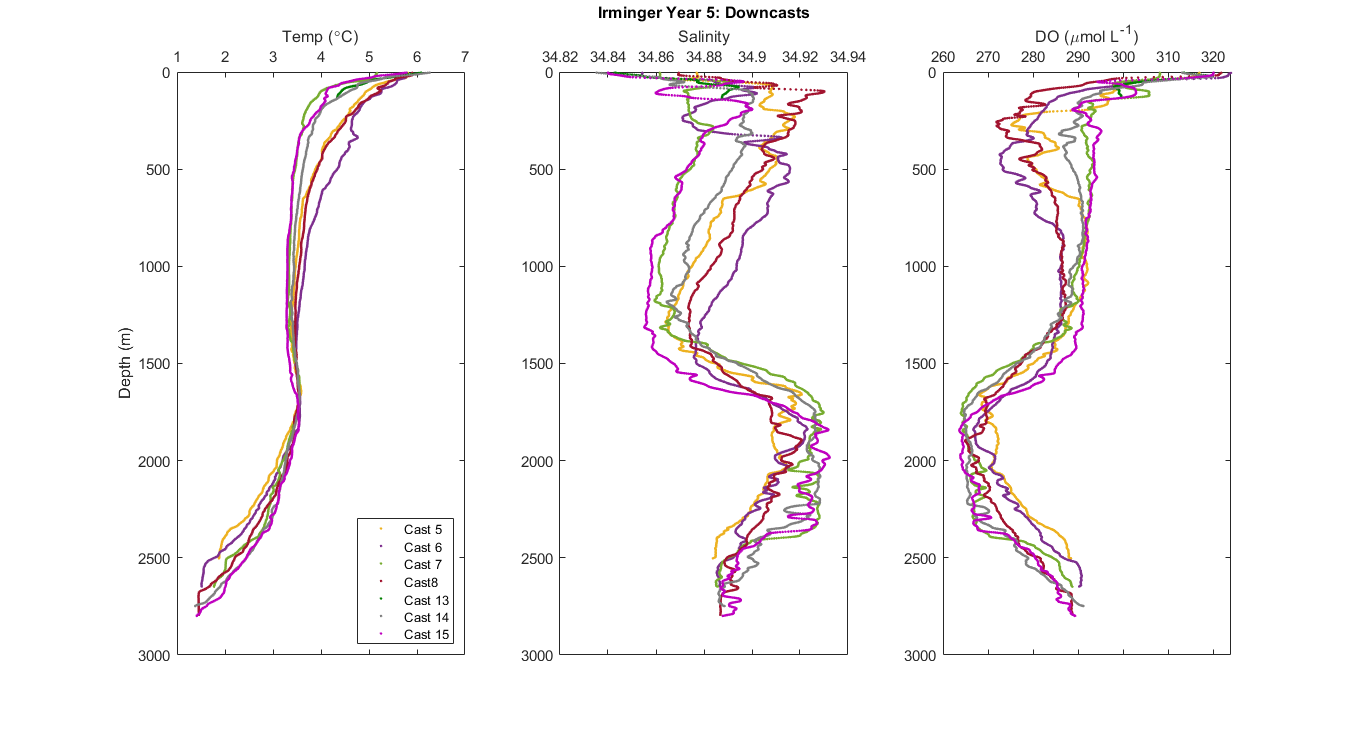

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3003005down.t090C,ar3003005down.depSM,'.','Color',yellow)
hold on
plot(ar3003006down.t090C,ar3003006down.depSM,'.','Color',purple)
plot(ar3003007down.t090C,ar3003007down.depSM,'.','Color',green)
plot(ar3003008down.t090C,ar3003008down.depSM,'.','Color',maroon)
plot(ar3003013down.t090C,ar3003013down.depSM,'.','Color',forestgreen)
plot(ar3003014down.t090C,ar3003014down.depSM,'.','Color',grey)
plot(ar3003015down.t090C,ar3003015down.depSM,'.','Color',brightpurple)
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 5','Cast 6','Cast 7','Cast8',...
    'Cast 13','Cast 14','Cast 15','Location','SE')

s2 = subplot(1,3,2);
plot(ar3003005down.sal00,ar3003005down.depSM,'.','Color',yellow)
hold on
plot(ar3003006down.sal00,ar3003006down.depSM,'.','Color',purple)
plot(ar3003007down.sal00,ar3003007down.depSM,'.','Color',green)
plot(ar3003008down.sal00,ar3003008down.depSM,'.','Color',maroon)
plot(ar3003013down.sal00,ar3003013down.depSM,'.','Color',forestgreen)
plot(ar3003014down.sal00,ar3003014down.depSM,'.','Color',grey)
plot(ar3003015down.sal00,ar3003015down.depSM,'.','Color',brightpurple)
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 5: Downcasts')

s3 = subplot(1,3,3);
plot(ar3003005down.sbeox0MLL*44.661,ar3003005down.depSM,'.','Color',yellow)
hold on
plot(ar3003006down.sbeox0MLL*44.661,ar3003006down.depSM,'.','Color',purple)
plot(ar3003007down.sbeox0MLL*44.661,ar3003007down.depSM,'.','Color',green)
plot(ar3003008down.sbeox0MLL*44.661,ar3003008down.depSM,'.','Color',maroon)
plot(ar3003013down.sbeox0MLL*44.661,ar3003013down.depSM,'.','Color',forestgreen)
plot(ar3003014down.sbeox0MLL*44.661,ar3003014down.depSM,'.','Color',grey)
plot(ar3003015down.sbeox0MLL*44.661,ar3003015down.depSM,'.','Color',brightpurple)
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

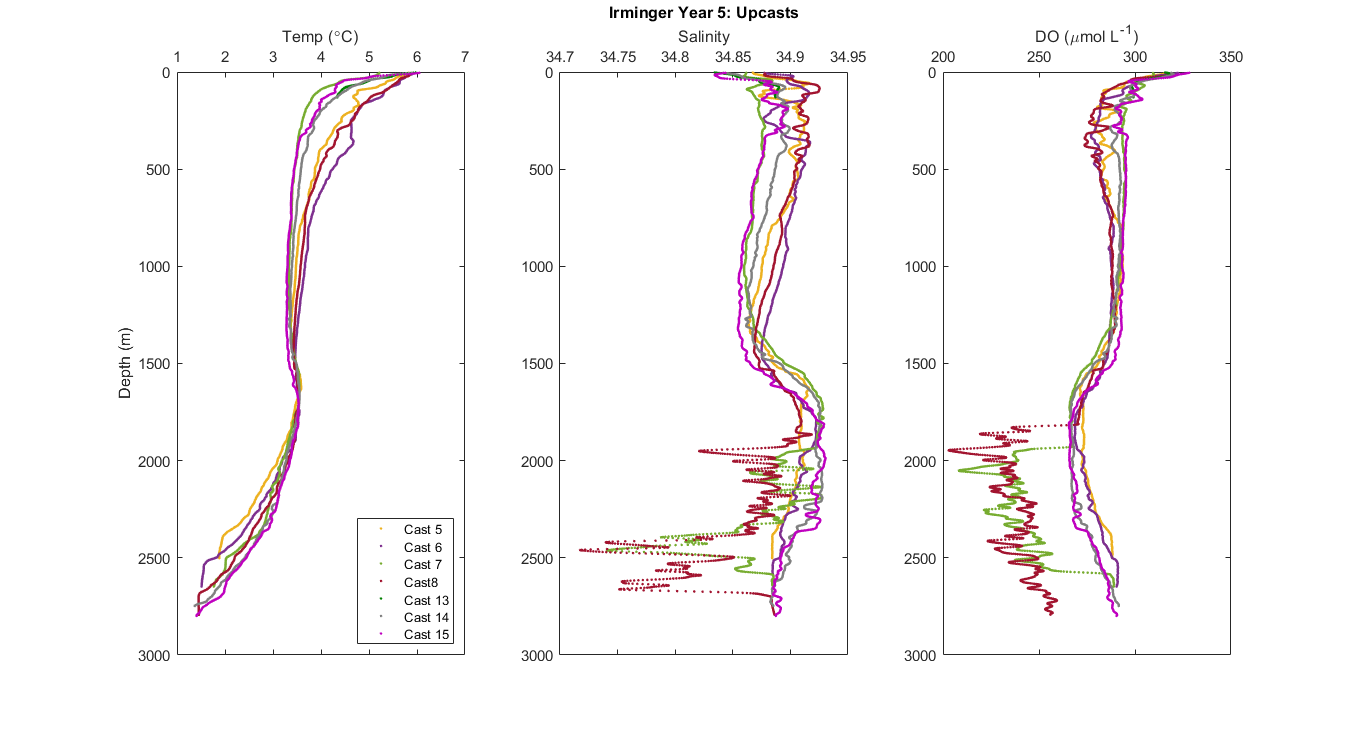

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3003005up.t090C,ar3003005up.depSM,'.','Color',yellow)
hold on
plot(ar3003006up.t090C,ar3003006up.depSM,'.','Color',purple)
plot(ar3003007up.t090C,ar3003007up.depSM,'.','Color',green)
plot(ar3003008up.t090C,ar3003008up.depSM,'.','Color',maroon)
plot(ar3003013up.t090C,ar3003013up.depSM,'.','Color',forestgreen)
plot(ar3003014up.t090C,ar3003014up.depSM,'.','Color',grey)
plot(ar3003015up.t090C,ar3003015up.depSM,'.','Color',brightpurple)
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 5','Cast 6','Cast 7','Cast8',...
    'Cast 13','Cast 14','Cast 15','Location','SE')

s2 = subplot(1,3,2);
plot(ar3003005up.sal00,ar3003005up.depSM,'.','Color',yellow)
hold on
plot(ar3003006up.sal00,ar3003006up.depSM,'.','Color',purple)
plot(ar3003007up.sal00,ar3003007up.depSM,'.','Color',green)
plot(ar3003008up.sal00,ar3003008up.depSM,'.','Color',maroon)
plot(ar3003013up.sal00,ar3003013up.depSM,'.','Color',forestgreen)
plot(ar3003014up.sal00,ar3003014up.depSM,'.','Color',grey)
plot(ar3003015up.sal00,ar3003015up.depSM,'.','Color',brightpurple)
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 5: Upcasts')

s3 = subplot(1,3,3);
plot(ar3003005up.sbeox0MLL*44.661,ar3003005up.depSM,'.','Color',yellow)
hold on
plot(ar3003006up.sbeox0MLL*44.661,ar3003006up.depSM,'.','Color',purple)
plot(ar3003007up.sbeox0MLL*44.661,ar3003007up.depSM,'.','Color',green)
plot(ar3003008up.sbeox0MLL*44.661,ar3003008up.depSM,'.','Color',maroon)
plot(ar3003013up.sbeox0MLL*44.661,ar3003013up.depSM,'.','Color',forestgreen)
plot(ar3003014up.sbeox0MLL*44.661,ar3003014up.depSM,'.','Color',grey)
plot(ar3003015up.sbeox0MLL*44.661,ar3003015up.depSM,'.','Color',brightpurple)
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

- Colors in CTD plots correspond to location colors in the map above. 

## Upcasts versus Downcasts 

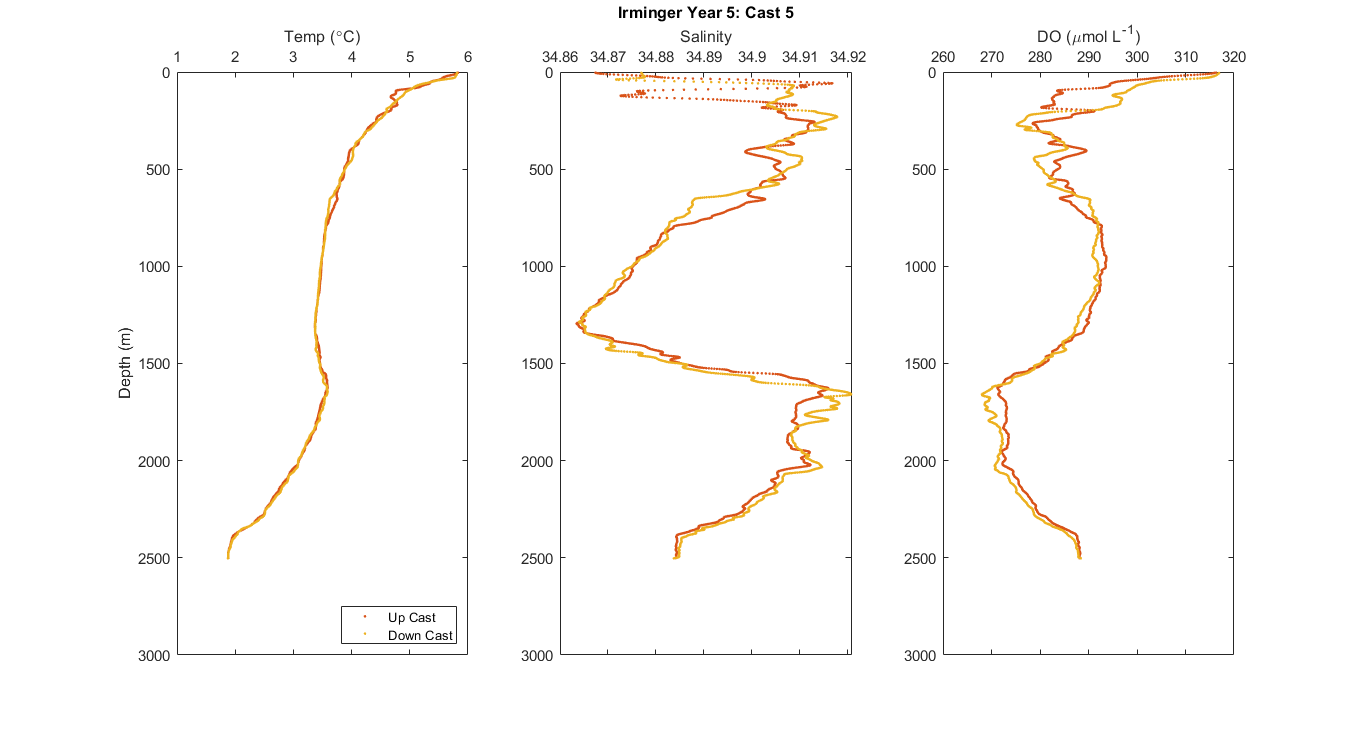

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3003005up.t090C,ar3003005up.depSM,'.','Color',red);
hold on
plot(ar3003005down.t090C,ar3003005down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3003005up.sal00,ar3003005up.depSM,'.','Color',red);
hold on
plot(ar3003005down.sal00,ar3003005down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 5: Cast 5')

s3 = subplot(1,3,3);
plot(ar3003005up.sbeox0MLL*44.661,ar3003005up.depSM,'.','Color',red);
hold on
plot(ar3003005down.sbeox0MLL*44.661,ar3003005down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

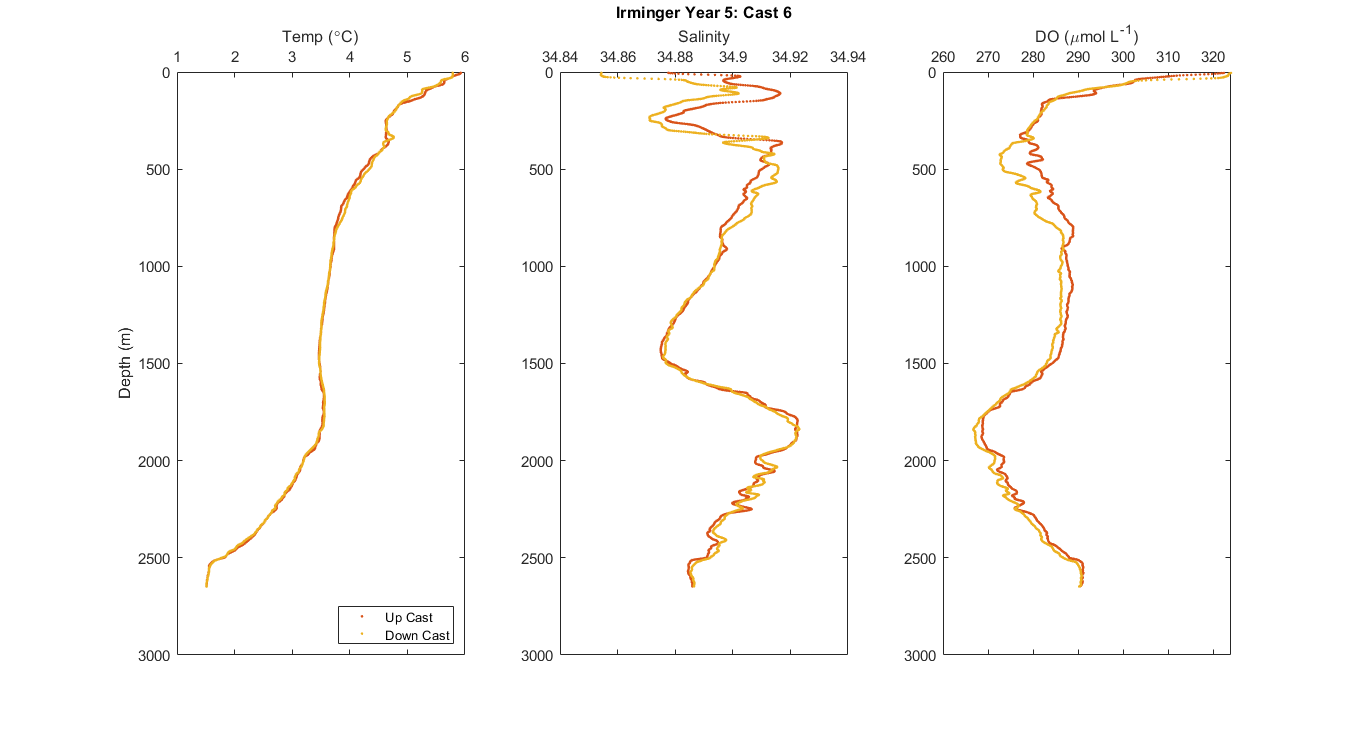

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3003006up.t090C,ar3003006up.depSM,'.','Color',red);
hold on
plot(ar3003006down.t090C,ar3003006down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3003006up.sal00,ar3003006up.depSM,'.','Color',red);
hold on
plot(ar3003006down.sal00,ar3003006down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 5: Cast 6')

s3 = subplot(1,3,3);
plot(ar3003006up.sbeox0MLL*44.661,ar3003006up.depSM,'.','Color',red);
hold on
plot(ar3003006down.sbeox0MLL*44.661,ar3003006down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

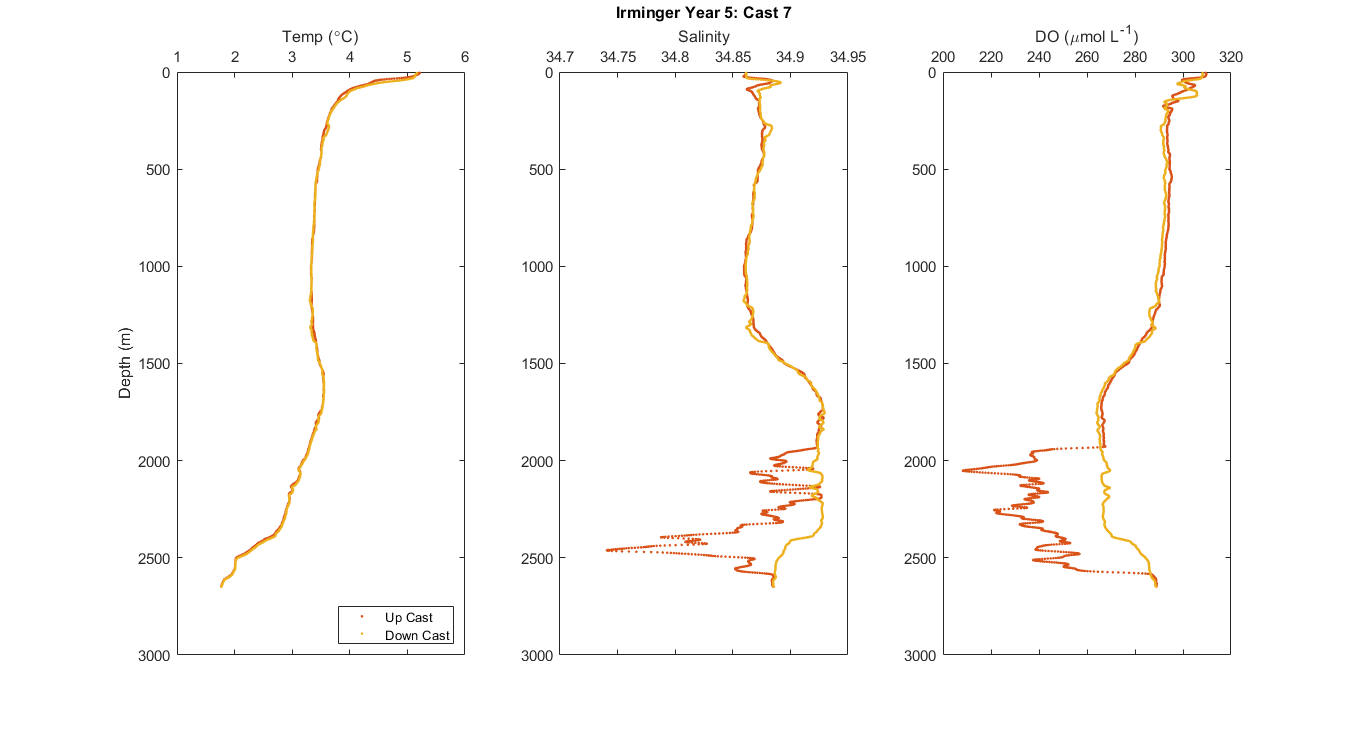

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3003007up.t090C,ar3003007up.depSM,'.','Color',red);
hold on
plot(ar3003007down.t090C,ar3003007down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3003007up.sal00,ar3003007up.depSM,'.','Color',red);
hold on
plot(ar3003007down.sal00,ar3003007down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 5: Cast 7')

s3 = subplot(1,3,3);
plot(ar3003007up.sbeox0MLL*44.661,ar3003007up.depSM,'.','Color',red);
hold on
plot(ar3003007down.sbeox0MLL*44.661,ar3003007down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

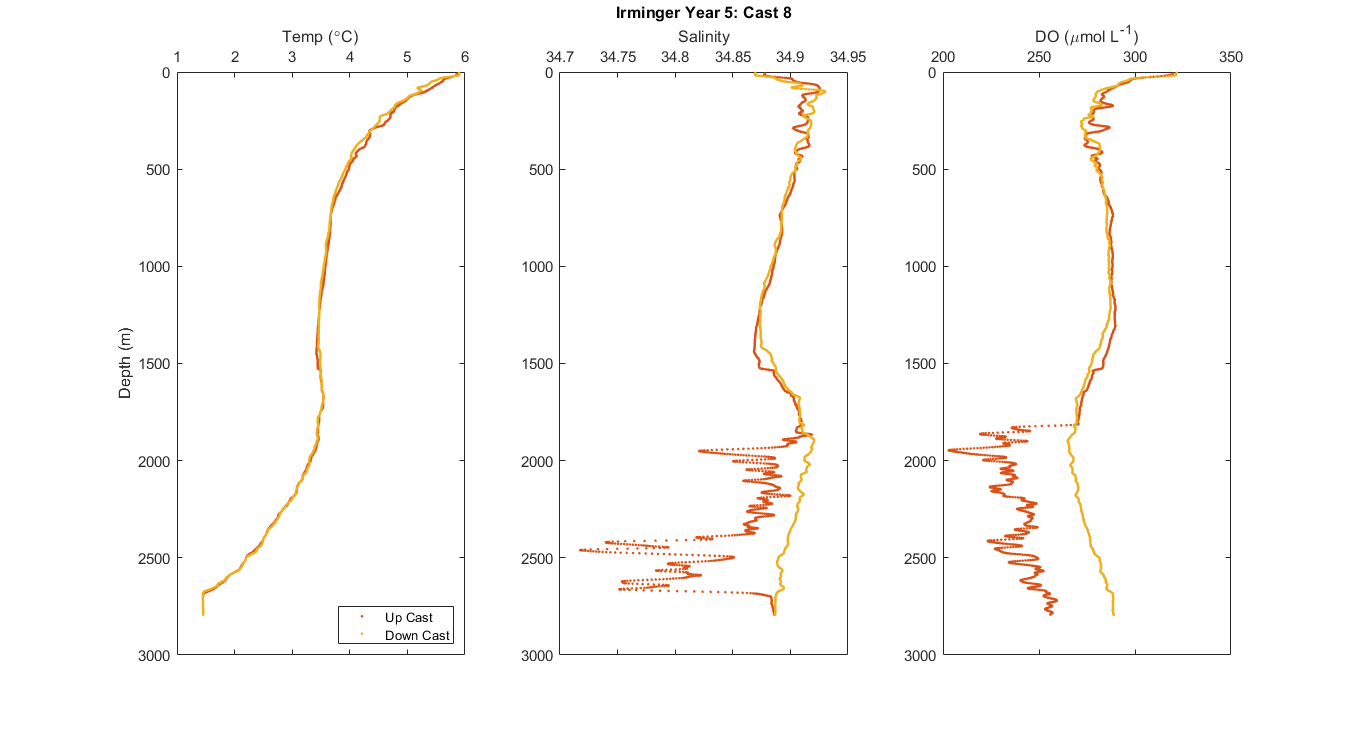

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3003008up.t090C,ar3003008up.depSM,'.','Color',red);
hold on
plot(ar3003008down.t090C,ar3003008down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3003008up.sal00,ar3003008up.depSM,'.','Color',red);
hold on
plot(ar3003008down.sal00,ar3003008down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 5: Cast 8')

s3 = subplot(1,3,3);
plot(ar3003008up.sbeox0MLL*44.661,ar3003008up.depSM,'.','Color',red);
hold on
plot(ar3003008down.sbeox0MLL*44.661,ar3003008down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

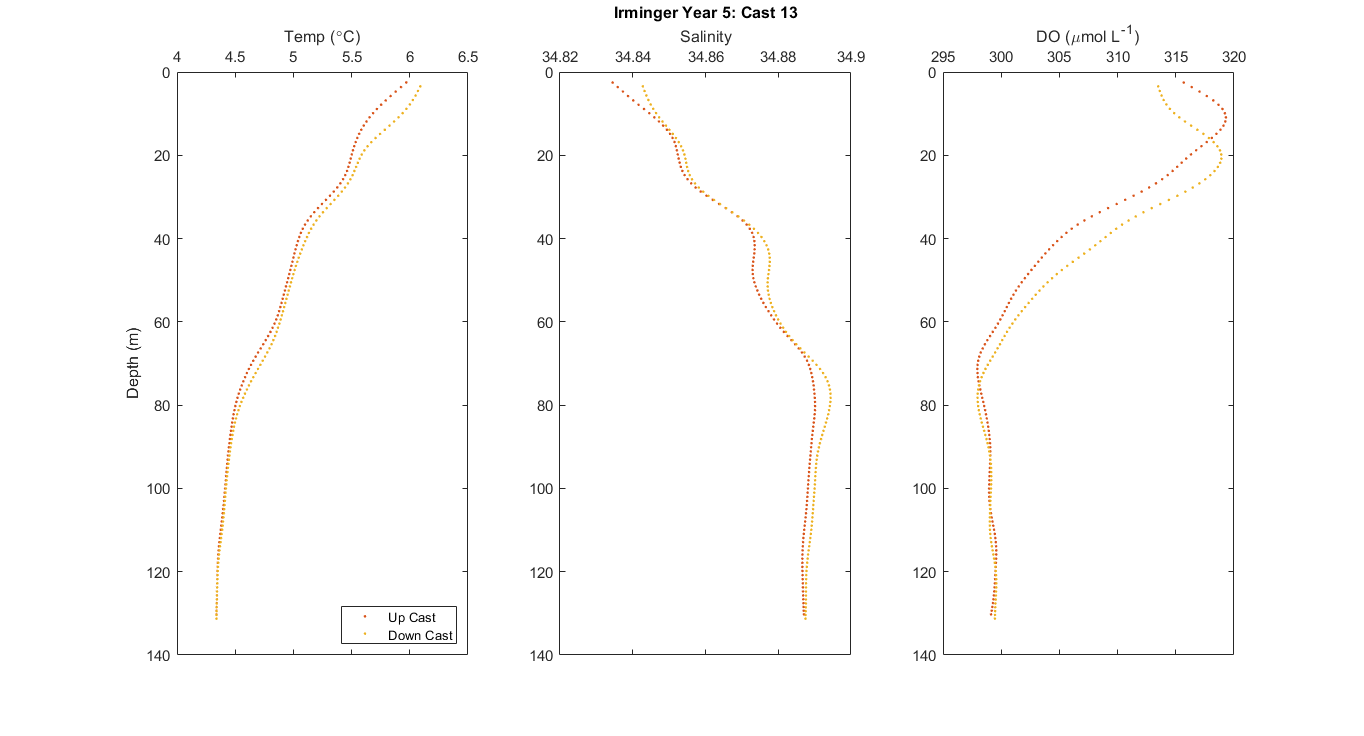


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3003013up.t090C,ar3003013up.depSM,'.','Color',red);
hold on
plot(ar3003013down.t090C,ar3003013down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3003013up.sal00,ar3003013up.depSM,'.','Color',red);
hold on
plot(ar3003013down.sal00,ar3003013down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 5: Cast 13')

s3 = subplot(1,3,3);
plot(ar3003013up.sbeox0MLL*44.661,ar3003013up.depSM,'.','Color',red);
hold on
plot(ar3003013down.sbeox0MLL*44.661,ar3003013down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

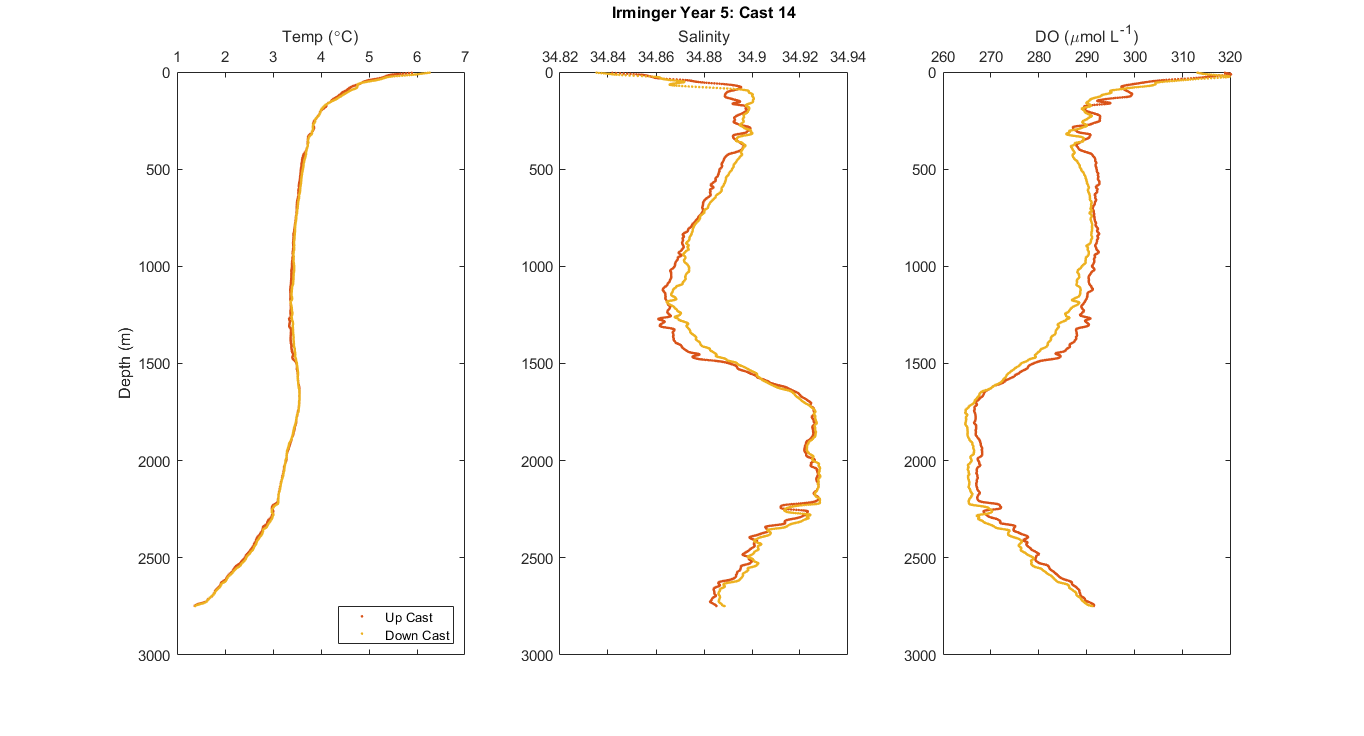


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3003014up.t090C,ar3003014up.depSM,'.','Color',red);
hold on
plot(ar3003014down.t090C,ar3003014down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3003014up.sal00,ar3003014up.depSM,'.','Color',red);
hold on
plot(ar3003014down.sal00,ar3003014down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 5: Cast 14')

s3 = subplot(1,3,3);
plot(ar3003014up.sbeox0MLL*44.661,ar3003014up.depSM,'.','Color',red);
hold on
plot(ar3003014down.sbeox0MLL*44.661,ar3003014down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

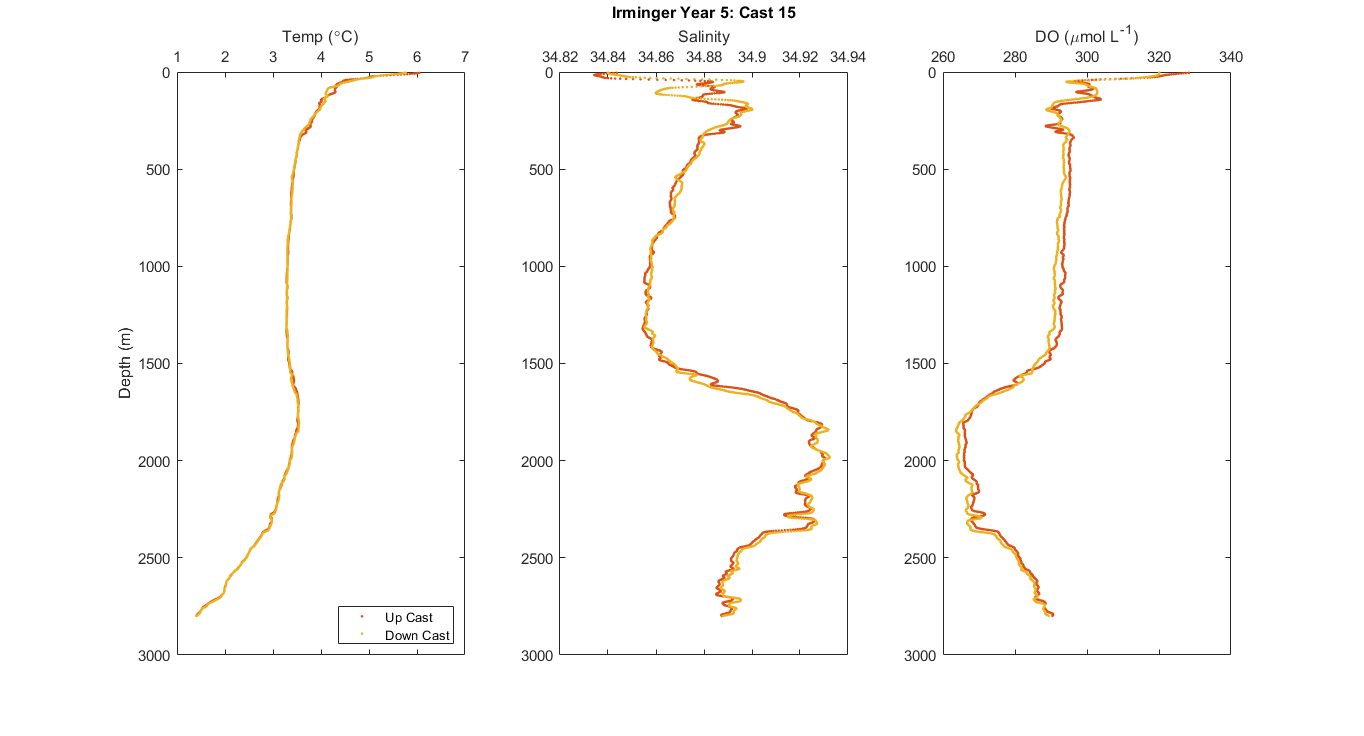


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar3003015up.t090C,ar3003015up.depSM,'.','Color',red);
hold on
plot(ar3003015down.t090C,ar3003015down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar3003015up.sal00,ar3003015up.depSM,'.','Color',red);
hold on
plot(ar3003015down.sal00,ar3003015down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 5: Cast 15')

s3 = subplot(1,3,3);
plot(ar3003015up.sbeox0MLL*44.661,ar3003015up.depSM,'.','Color',red);
hold on
plot(ar3003015down.sbeox0MLL*44.661,ar3003015down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')